## Homework 4: Graph Spectra

#### `Team Members: Noel Karlsson Johansson, Alexander Olsson`

### `Instructions:`

`1. Download the dataset from the link on canvas`

`2. Place the file in the same directory as this file`

`3. Run the code`

## Read data

clear all
k_1 = 4;
k_2 = 2;
E_1 = csvread('example1.dat');
E_2 = csvread('example2.dat');


## Step 1

Step 1 of spectral clustring algorithm

We also display the sparsity pattern which helps to identify the number of clusters

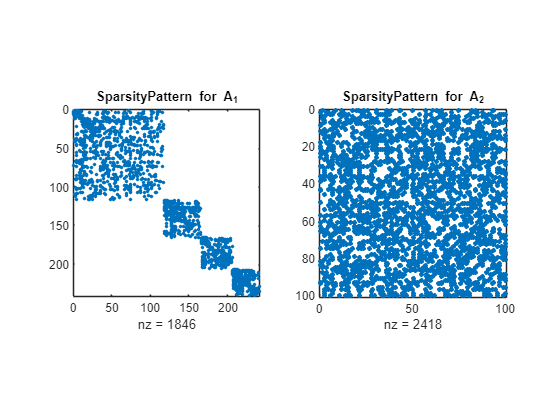

A_1 = step1(E_1);
A_2 = step1(E_2);
% Plot
figure(1);
subplot(1,2,1);
spy(A_1);
title("SparsityPattern for A_1");
subplot(1,2,2);
spy(A_2);
title("SparsityPattern for A_2");

## Graph plot

Visualing the Graph can help to guess the number of clusters

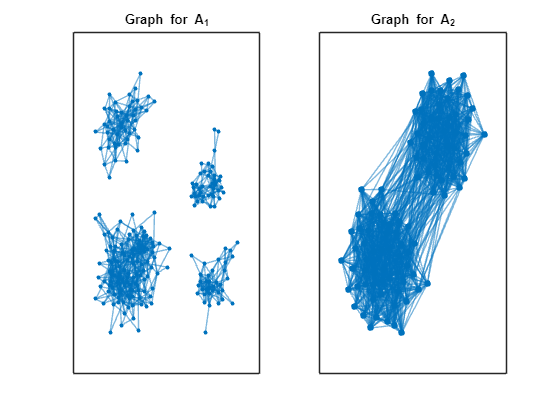

figure(2);
subplot(1,2,1);
plot(graph(A_1), 'Layout','force');
title("Graph for A_1");
subplot(1,2,2);
plot(graph(A_2),'Layout', 'force', 'NodeLabel', {});
title("Graph for A_2");

## Step 2-5

[clusters_1, L_1] = step2_5(A_1, k_1);
[clusters_2, L_2] = step2_5(A_2, k_2);

## Step 6

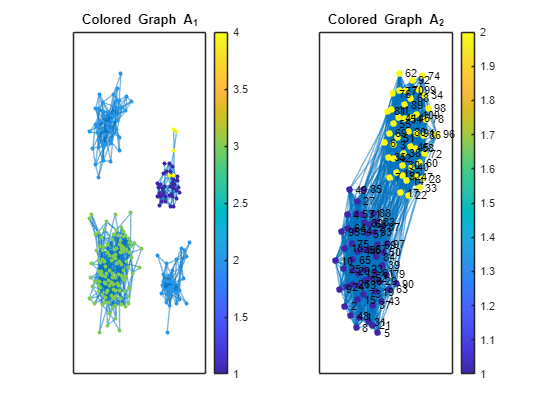

% Assign different colors to each cluster
figure(3);
subplot(1,2,1);
h=plot(graph(A_1), 'Layout','force');
h.NodeCData = clusters_1;
% Display colorbar
title("Colored Graph A_1");
colorbar;
subplot(1,2,2);
h_2=plot(graph(A_2), 'Layout','force');
h_2.NodeCData = clusters_2;
% Display colorbar
title("Colored Graph A_2");
colorbar;

## Sorted Fiedler Vector

The Fiedler vector is a special eigenvector of the Laplacian matrix that is used to partition a graph into two parts. The Fiedler vector corresponds to the second smallest eigenvalue of the Laplacian matrix and is used to bi-partition the graph by placing all points whose component in the Fiedler vector is positive in one set and the rest in another set.

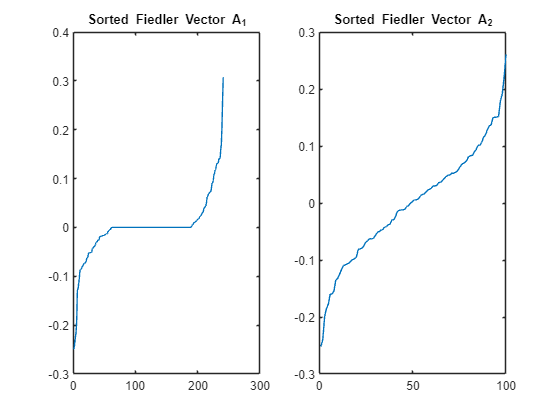

[V_1,D] = eigs(L_1, 2, 'SA');
[V_2,D] = eigs(L_2, 2, 'SA');
figure(4);
subplot(1,2,1);
plot(sort(V_1(:,2)), '-');
title("Sorted Fiedler Vector A_1")
subplot(1,2,2);
plot(sort(V_2(:,2)), '-');
title("Sorted Fiedler Vector A_2");

### Functions

function [A] = step1(E)
    col1 = E(:,1);
    col2 = E(:,2);
    max_ids = max(max(col1,col2));
    As= sparse(col1, col2, 1, max_ids, max_ids); 
    A = full(adjacency(graph(As)));
end
function [clusters, L] = step2_5(A, k)
    D = diag(sum(A,2));
    L = (D^(-1/2))*A*(D^(-1/2));
    
    %% Step 3
    [v, D] = eigs(L, k);
    
    %% Step 4
    Y = v./sum(v.*v,2).^(1/2);
    
    %% Step 5
    clusters = kmeans(Y, k);
end